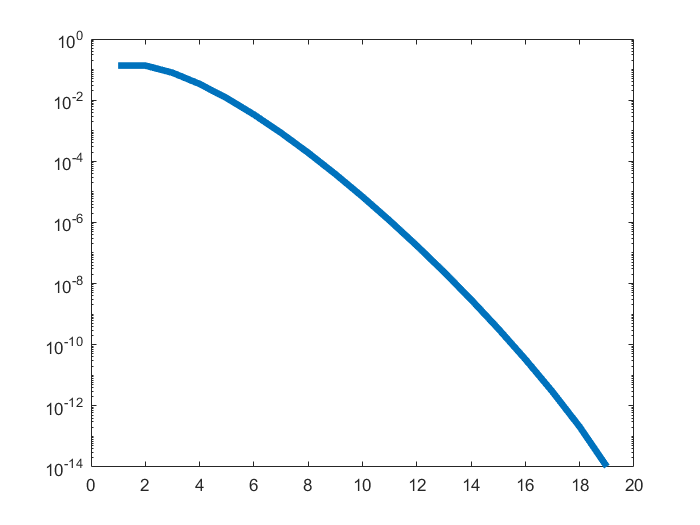

x = 1:10;
P1 = poisspdf(x,1);

D2 = conv(P1,P1);
plot(D2,"LineWidth",4)
set(gca,'YScale','log')

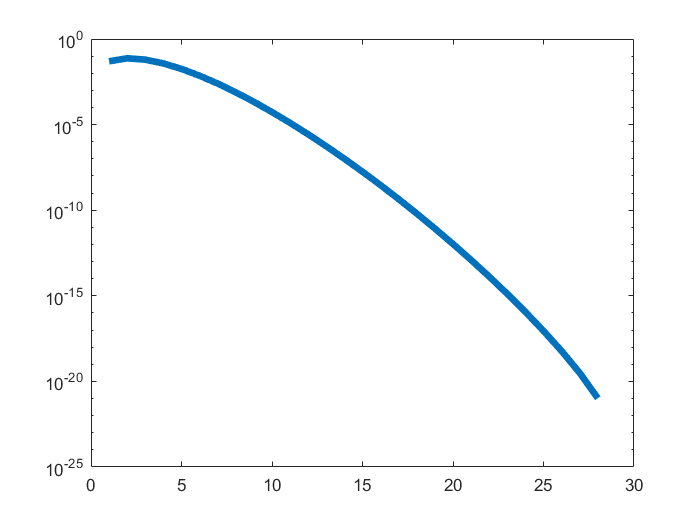

D3 = conv(D2,P1);
plot(D3,"LineWidth",4)
set(gca,'YScale','log')

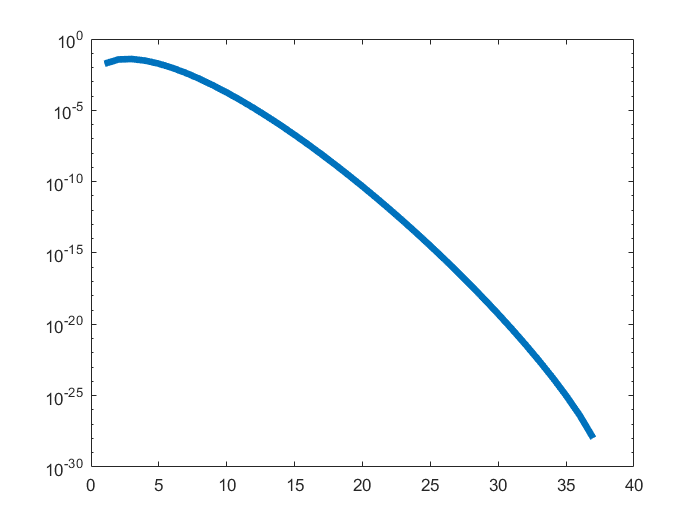

D4 = conv(D3,P1);
plot(D4,"LineWidth",4)
set(gca,'YScale','log')

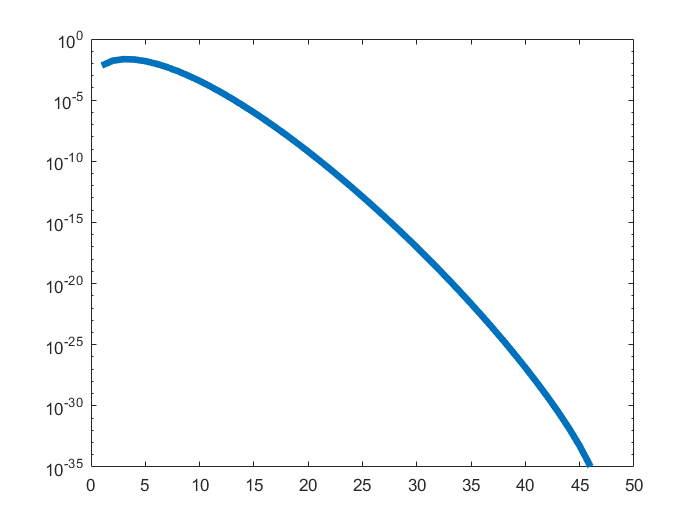

D5 = conv(D4,P1);
plot(D5,"LineWidth",4)
set(gca,'YScale','log')

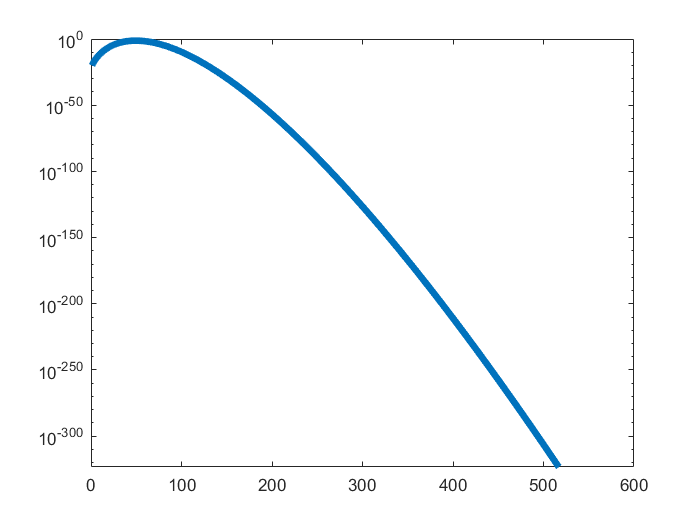


Test = poisspdf(1:1000,50);
plot(Test,"LineWidth",4)
set(gca,'YScale','log')

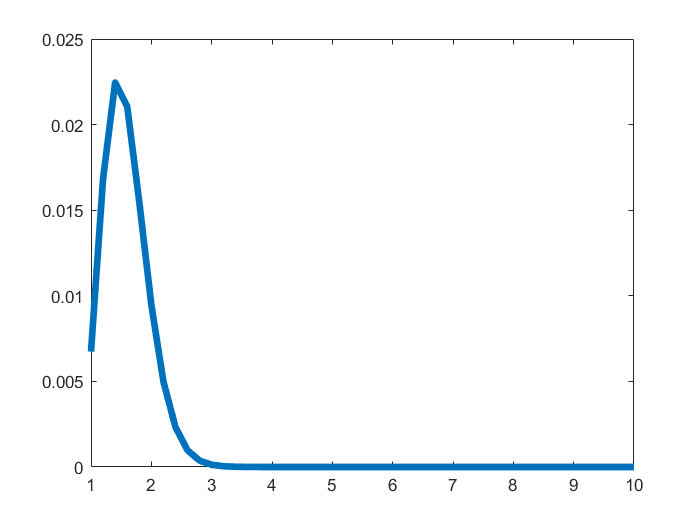


cx = 1:(1/5):10;
plot(cx,D5,"LineWidth",4);

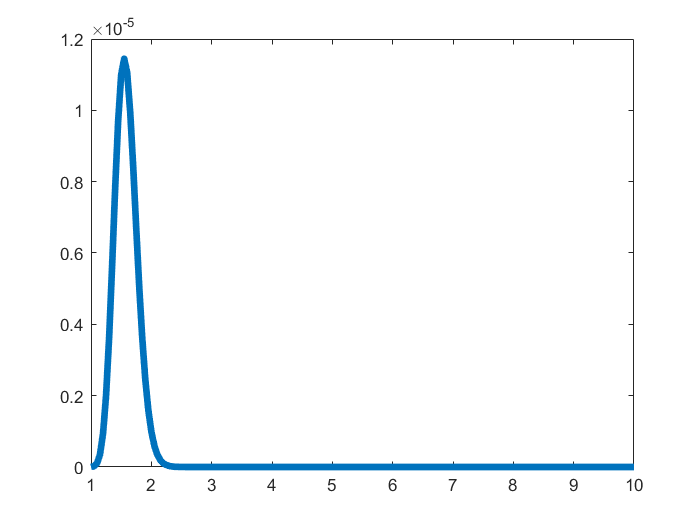


D10 = conv(D5,D5);
D20 = conv(D10,D10);

cx = 1:(1/20):10;
plot(cx,D20,"LineWidth",4);

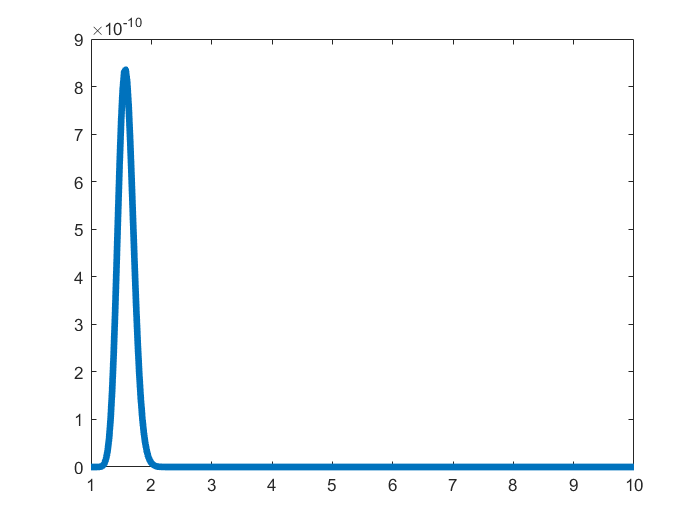


D40 = conv(D20,D20);

cx = 1:(1/40):10;
 plot(cx,D40,"LineWidth",4);


N = 10;
Y = 2;
T = Y*N;

X1 = poisscdf(T,N,"upper")

X1 = 0.0016

Z1 = norminv(X1,N)

Z1 = 7.0499

Problem 2

x = linspace(0,40,1000);
X1 = chi2pdf(x,4.5);

Xn = X1;
for n = 1:10
    Xn = conv(Xn,X1);
end

X1 = X1 / sum(X1);
Xi = X1;
for i = 1:150
    Xi = conv(Xi,X1);
end

Problem 3

Signal = 5.43;
Width = 1;
% logN = makedist("Normal",'mu',0,'sigma',Width);
Dist = normpdf(-5:5,0,Width);
PD1 = normcdf(Signal,0,Width)

PD1 = 1.0000

SIGMA = norminv(PD1,0,Width)

SIGMA = 5.4300

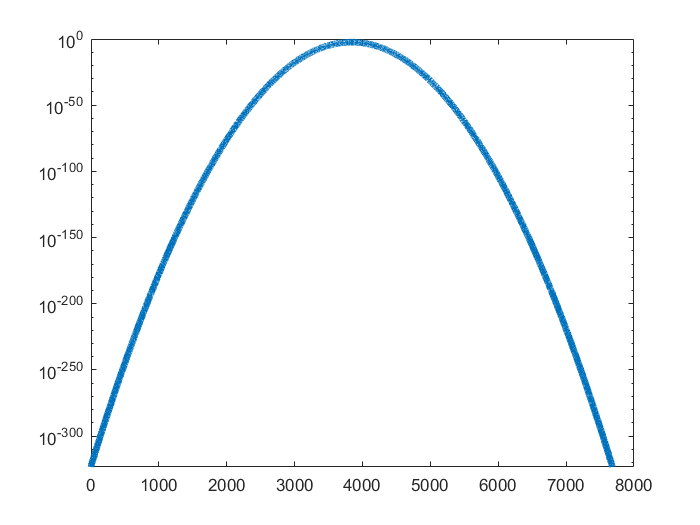


Prob = Dist;
Prob = Prob / sum(Prob);
Total = Prob;
for i = 1:10000
    Total = conv(Total,Prob);
end
Total = nonzeros(Total);

plot(Total,'linewidth',4)
set(gca,'Yscale','log')


sel = Signal*10^3:7679;
PD10k =  sum(Total(sel))

PD10k = 3.4713e-57

sigma10K = norminv(PD10k,0,10000*Width)

sigma10K = -1.5894e+05

Problem 4

prob5 = normcdf(5);
probless = 1 - prob5;

Ndist = normrnd(0,Width,10000);
signal1 = find(Ndist > probless);
count1 = signal1(1)

count1 = 2



signal10k = find(Total > probless);
count10k = signal10k(1)

count10k = 3404

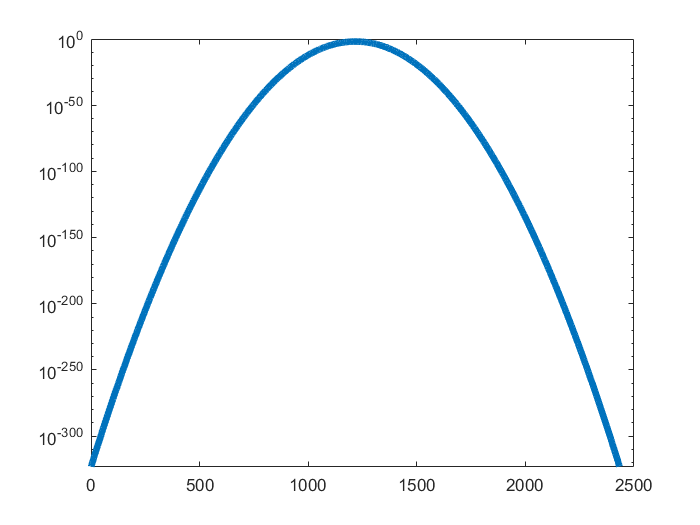


Signal1k = 1.5;
Totalalot = Prob;
for n = 1:1000
    Totalalot = conv(Totalalot,Prob);
end
Totalalot = nonzeros(Totalalot);

plot(Totalalot,'linewidth',4)
set(gca,'Yscale','log')


selalot = Signal1k*10^3:2433;
PD1k = sum(Totalalot(selalot))

PD1k = 2.1427e-19

sigma1k = norminv(PD1k,0,1000*Width)

sigma1k = -8.9293e+03